clc;
clear;
clearAllMemoizedCaches;

% Defining the variables and constants
syms vo vin v1 v2 v3 C0 R0 s

% Defining the system of equations
eq1 = C0*s * (vo - v1) + (vo - v3)/R0 == 0;
eq2 = C0*s * (v1 - vin) + C0*s * (v1 - vo) + (v1 - v2)/(R0/2) == 0;
eq3 = (v2 - v1)/(R0/2) + v2/200 + (v2 - vo)/10 + (v2 - v3) * 2*C0*s == 0;
eq4 = 2*C0*s * (v3 - v2) + (v3 - vin)/R0 + (v3 - vo)/R0 == 0;
 
% Solving the system of equations based for [vo,vin,v1,v2,v3] based on the
% remaining variables
sol = solve([eq1, eq2, eq3, eq4], [vo,v1,v2,v3]);
sol_vo = simplify(sol.vo);

% H(s) the Transfer Function (vo(s)/vin(s))
H = simplify(sol_vo / vin);
disp("Parametric Transfer Function: ");

Parametric Transfer Function: 


disp(H);

$$\frac{21\,{C_{0}}^{2}\,{R_{0}}^{2}\,s^{2}+800\,{C_{0}}^{2}\,R_{0}\,s^{2}+800\,C_{0}\,s+21}{21\,{C_{0}}^{2}\,{R_{0}}^{2}\,s^{2}+800\,{C_{0}}^{2}\,R_{0}\,s^{2}+4\,C_{0}\,R_{0}\,s+800\,C_{0}\,s+21}$$

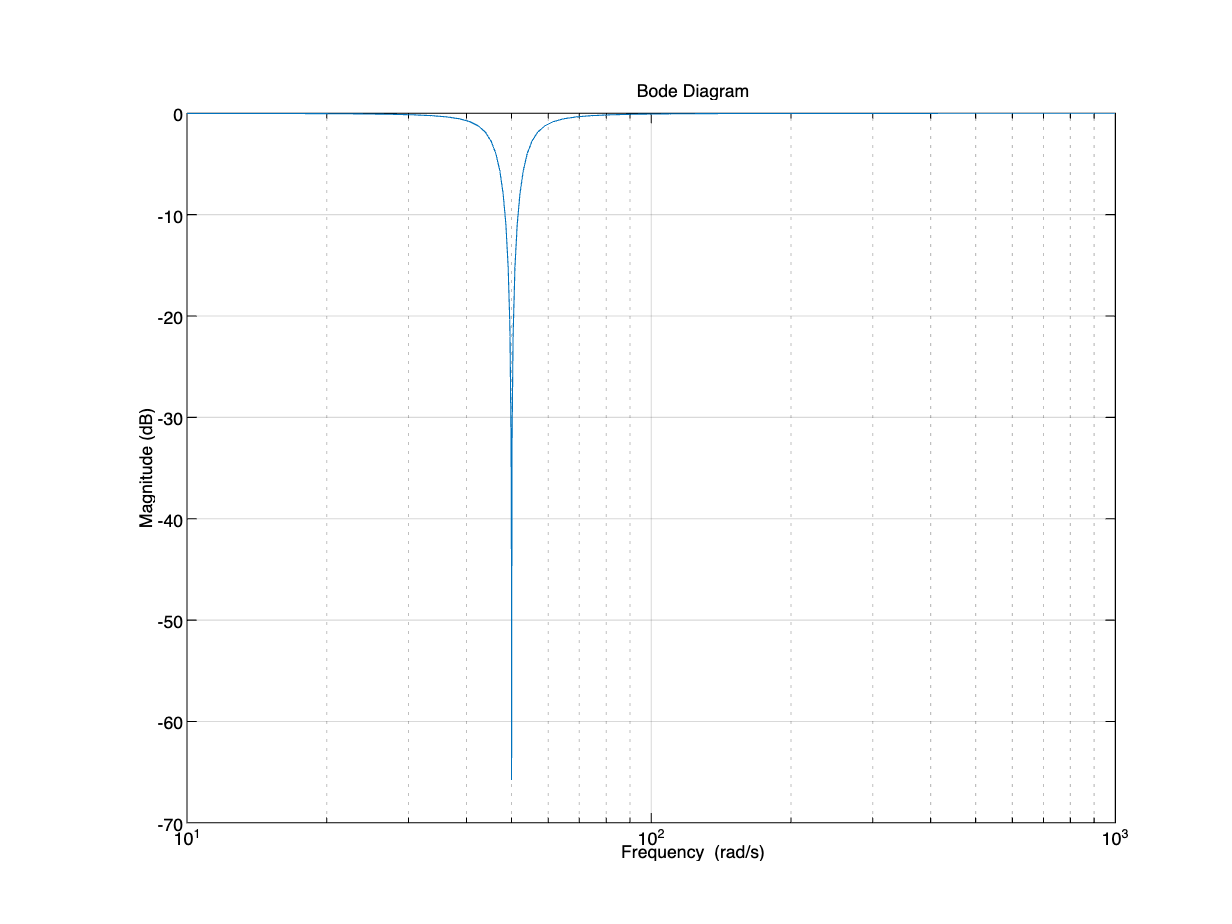


% Substituting proper values in H(s)
f = sym("f");
H = subs(H,[C0,R0,s],[8.2e-9,388e3,2*pi*f]);

% Convert symbolic transfer function H to numeric transfer function
[num, den] = numden(H);          % Separate numerator and denominator
num_coeffs = double(coeffs(num, f, 'All')); % Get numeric coefficients of numerator
den_coeffs = double(coeffs(den, f, 'All')); % Get numeric coefficients of denominator

% Create transfer function
H_tf = tf(num_coeffs, den_coeffs);

% Plot the transfer function
options = bodeoptions;
set(options,'PhaseVisible','off');
bode(H_tf,options);
grid on;

## Tolerance analysis.

% Monte Carlo Analysis
clc;
clear;

% Number of simulations
number_of_simulations = 1000;

% Defining symbolic transfer function H(s)
syms vo vin v1 v2 v3 C1 C2 C3 R1 R2 R3 s
eq1 = C2*s * (vo - v1) + (vo - v3)/R2 == 0;
eq2 = C1*s * (v1 - vin) + C2*s * (v1 - vo) + (v1 - v2)/R3 == 0;
eq3 = (v2 - v1)/R3 + v2/200 + (v2 - vo)/10 + (v2 - v3) * C3*s == 0;
eq4 = C3*s * (v3 - v2) + (v3 - vin)/R1 + (v3 - vo)/R2 == 0;

solutions = solve([eq1,eq2,eq3,eq4],[v1,v2,v3,vo]);
solVo = simplify(solutions.vo);
H_format = simplify(solVo/vin);
disp(H_format);

$$\begin{array}{l} \frac{200\,C_{1}\,s+200\,C_{2}\,s+200\,C_{3}\,s+21\,C_{1}\,R_{3}\,s+21\,C_{2}\,R_{3}\,s+\sigma_{12}+\sigma_{11}+\sigma_{10}+\sigma_{9}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}+21}{200\,C_{1}\,s+200\,C_{2}\,s+200\,C_{3}\,s+C_{2}\,R_{1}\,s+21\,C_{1}\,R_{3}\,s+C_{2}\,R_{2}\,s+C_{3}\,R_{1}\,s+21\,C_{2}\,R_{3}\,s+\sigma_{12}+\sigma_{11}+\sigma_{10}+\sigma_{9}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+C_{1}\,C_{3}\,R_{1}\,R_{3}\,s^{2}+C_{2}\,C_{3}\,R_{1}\,R_{2}\,s^{2}+C_{2}\,C_{3}\,R_{1}\,R_{3}\,s^{2}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}+21}\\ \mathrm{where}\\ \sigma_{1}=21\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{2}\,R_{3}\,s^{3}\\ \sigma_{2}=200\,C_{1}\,C_{2}\,C_{3}\,R_{2}\,R_{3}\,s^{3}\\ \sigma_{3}=200\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{3}\,s^{3}\\ \sigma_{4}=200\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{2}\,s^{3}\\ \sigma_{5}=21\,C_{1}\,C_{2}\,R_{2}\,R_{3}\,s^{2}\\ \sigma_{6}=21\,C_{1}\,C_{2}\,R_{1}\,R_{3}\,s^{2}\\ \sigma_{7}=200\,C_{2}\,C_{3}\,R_{3}\,s^{2}\\ \sigma_{8}=200\,C_{2}\,C_{3}\,R_{2}\,s^{2}\\ \sigma_{9}=200\,C_{1}\,C_{3}\,R_{3}\,s^{2}\\ \sigma_{10}=200\,C_{1}\,C_{3}\,R_{1}\,s^{2}\\ \sigma_{11}=200\,C_{1}\,C_{2}\,R_{2}\,s^{2}\\ \sigma_{12}=200\,C_{1}\,C_{2}\,R_{1}\,s^{2} \end{array}$$

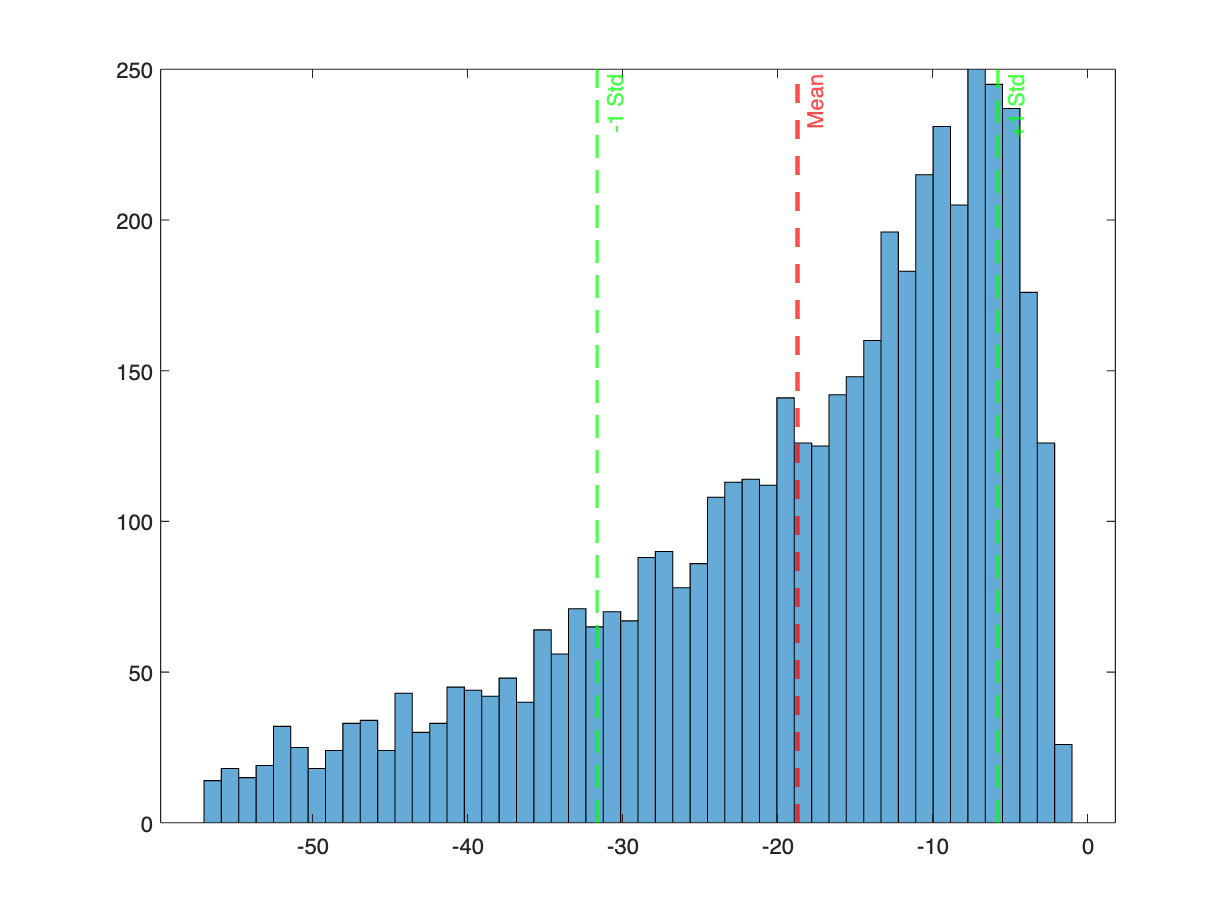

    % Definning Elements and Tolerances        
    R1_mean = 388e3;            
    R1_tolerance = 0.05;            
    R1_samples =  normrnd(R1_mean, R1_mean * R1_tolerance, number_of_simulations, 1);
    R2_mean = 388e3;
    R2_tolerance = 0.05;
    R2_samples =  normrnd(R2_mean, R2_mean * R2_tolerance, number_of_simulations, 1);            
    R3_mean = 194e3;
    R3_tolerance = 0.05;            
    R3_samples =  normrnd(R3_mean, R3_mean * R3_tolerance, number_of_simulations, 1);            
    C1_mean = 8.2e-9;            
    C1_tolerance = 0.05;            
    C1_samples =  normrnd(C1_mean, C1_mean * C1_tolerance, number_of_simulations, 1);            
    C2_mean = 8.2e-9;            
    C2_tolerance = 0.05;            
    C2_samples =  normrnd(C2_mean, C2_mean * C2_tolerance, number_of_simulations, 1);            
    C3_mean = 16.4e-9;            
    C3_tolerance = 0.05;            
    C3_samples =  normrnd(C3_mean, C3_mean * C3_tolerance, number_of_simulations, 1);

    R_mean = 388e3;
    C_mean = 8.2e-9;
    frequency = 1 / (2 * pi * R_mean * C_mean);
    w = 2 * pi * frequency;
    s_value = 1i * w;
    gains = zeros(number_of_simulations, 1);
    H_samples = zeros(number_of_simulations, 7); % [[R1,R2,R3,C1,C2,C3,gain], ...]

    % Monte Carlo simulation
    for i = 1:number_of_simulations
        H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_samples(i),R2_samples(i),R3_samples(i),C1_samples(i),C2_samples(i),C3_samples(i),s_value]);
        gains(i) = 20 * log10(abs(double(H)));
        H_samples(i, :) = [R1_samples(i),R2_samples(i),R3_samples(i),C1_samples(i),C2_samples(i),C3_samples(i),gains(i)];
    end

    % Sort results based on gains
    sorted_tfs = sortrows(H_samples, 7);
    
    % Extract first quartile, mean, and third quartile
    q1_index = round(0.25 * number_of_simulations);
    q3_index = round(0.75 * number_of_simulations);
    mean_index = round(0.5 * number_of_simulations);

    % Generate transfer functions for quartiles and mean
    quartiles = [q1_index, mean_index, q3_index];
    tf_list = cell(1, 3);
    f = sym("f");
    for j = 1:3
        R1_val = sorted_tfs(quartiles(j), 1);
        R2_val = sorted_tfs(quartiles(j), 2);
        R3_val = sorted_tfs(quartiles(j), 3);
        C1_val = sorted_tfs(quartiles(j), 4);
        C2_val = sorted_tfs(quartiles(j), 5);
        C3_val = sorted_tfs(quartiles(j), 6);
        Hq = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_val,R2_val,R3_val,C1_val,C2_val,C3_val, 2*pi*f]);
        [num, den] = numden(Hq); % Separate numerator and denominator
        num_coeffs = double(coeffs(num, f, 'All')); % Get numeric coefficients of numerator
        den_coeffs = double(coeffs(den, f, 'All')); % Get numeric coefficients of denominator
        tf_list{j} = tf(num_coeffs, den_coeffs); % Create transfer function
    end

    % Plot Bode diagrams for the quartiles and mean
    figure;
    options = bodeoptions;
    options.PhaseVisible = 'off';
    hold on;
    bode(tf_list{1}, {10, 100}, options);
    bode(tf_list{2}, {10, 100}, options);
    bode(tf_list{3}, {10, 100}, options);
    grid on;
    title('Bode Plot');
    legend('1st Quartile', 'Mean', '3rd Quartile');
    hold off;

    % Plot Histogram of gain at notch frequency
    figure;
    gains = rmoutliers(gains);
    mean_gain = mean(gains);
    std_gain = std(gains);
    histogram(gains,50);
    xline(mean_gain, '--r', 'LineWidth', 2, 'Label', 'Mean');
    xline(mean_gain + std_gain, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(mean_gain - std_gain, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

## Individual elements' tolerances analysis.

% Monte Carlo Analysis
clc;
clear;

% Number of simulations
number_of_simulations = 1000;

% Defining symbolic transfer function H(s)
syms vo vin v1 v2 v3 C1 C2 C3 R1 R2 R3 s
eq1 = C2*s * (vo - v1) + (vo - v3)/R2 == 0;
eq2 = C1*s * (v1 - vin) + C2*s * (v1 - vo) + (v1 - v2)/R3 == 0;
eq3 = (v2 - v1)/R3 + v2/200 + (v2 - vo)/10 + (v2 - v3) * C3*s == 0;
eq4 = C3*s * (v3 - v2) + (v3 - vin)/R1 + (v3 - vo)/R2 == 0;

solutions = solve([eq1,eq2,eq3,eq4],[v1,v2,v3,vo]);
solVo = simplify(solutions.vo);
H_format = simplify(solVo/vin);
disp(H_format);

$$\begin{array}{l} \frac{200\,C_{1}\,s+200\,C_{2}\,s+200\,C_{3}\,s+21\,C_{1}\,R_{3}\,s+21\,C_{2}\,R_{3}\,s+\sigma_{12}+\sigma_{11}+\sigma_{10}+\sigma_{9}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}+21}{200\,C_{1}\,s+200\,C_{2}\,s+200\,C_{3}\,s+C_{2}\,R_{1}\,s+21\,C_{1}\,R_{3}\,s+C_{2}\,R_{2}\,s+C_{3}\,R_{1}\,s+21\,C_{2}\,R_{3}\,s+\sigma_{12}+\sigma_{11}+\sigma_{10}+\sigma_{9}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+C_{1}\,C_{3}\,R_{1}\,R_{3}\,s^{2}+C_{2}\,C_{3}\,R_{1}\,R_{2}\,s^{2}+C_{2}\,C_{3}\,R_{1}\,R_{3}\,s^{2}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}+21}\\ \mathrm{where}\\ \sigma_{1}=21\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{2}\,R_{3}\,s^{3}\\ \sigma_{2}=200\,C_{1}\,C_{2}\,C_{3}\,R_{2}\,R_{3}\,s^{3}\\ \sigma_{3}=200\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{3}\,s^{3}\\ \sigma_{4}=200\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{2}\,s^{3}\\ \sigma_{5}=21\,C_{1}\,C_{2}\,R_{2}\,R_{3}\,s^{2}\\ \sigma_{6}=21\,C_{1}\,C_{2}\,R_{1}\,R_{3}\,s^{2}\\ \sigma_{7}=200\,C_{2}\,C_{3}\,R_{3}\,s^{2}\\ \sigma_{8}=200\,C_{2}\,C_{3}\,R_{2}\,s^{2}\\ \sigma_{9}=200\,C_{1}\,C_{3}\,R_{3}\,s^{2}\\ \sigma_{10}=200\,C_{1}\,C_{3}\,R_{1}\,s^{2}\\ \sigma_{11}=200\,C_{1}\,C_{2}\,R_{2}\,s^{2}\\ \sigma_{12}=200\,C_{1}\,C_{2}\,R_{1}\,s^{2} \end{array}$$


R1_value = 388e3;
R2_value = 388e3;
R3_value = 194e3;
C1_value = 8.2e-9;
C2_value = 8.2e-9;
C3_value = 16.4e-9;
elements = ["R1","R2","R3","C1","C2","C3"];

for var = elements
    switch (var)
        case "R1"
            R1_mean = 388e3;
            R1_tolerance = 0.05;
            R1_samples =  normrnd(R1_mean, R1_mean * R1_tolerance, number_of_simulations, 1);
        case "R2"
            R2_mean = 388e3;
            R2_tolerance = 0.05;
            R2_samples =  normrnd(R2_mean, R2_mean * R2_tolerance, number_of_simulations, 1);
        case "R3"
            R3_mean = 194e3;
            R3_tolerance = 0.05;
            R3_samples =  normrnd(R3_mean, R3_mean * R3_tolerance, number_of_simulations, 1);
        case "C1"
            C1_mean = 8.2e-9;
            C1_tolerance = 0.05;
            C1_samples =  normrnd(C1_mean, C1_mean * C1_tolerance, number_of_simulations, 1);
        case "C2"
            C2_mean = 8.2e-9;
            C2_tolerance = 0.05;
            C2_samples =  normrnd(C2_mean, C2_mean * C2_tolerance, number_of_simulations, 1);
        case "C3"
            C3_mean = 16.4e-9;
            C3_tolerance = 0.05;
            C3_samples =  normrnd(C3_mean, C3_mean * C3_tolerance, number_of_simulations, 1);
        otherwise
            disp("Error");
   end

    % Preallocate arrays for gains and transfer functions
    R_mean = 388e3;
    C_mean = 8.2e-9;
    frequency = 1 / (2 * pi * R_mean * C_mean);
    w = 2 * pi * frequency;
    s_value = 1i * w;
    gains = zeros(number_of_simulations, 1);
    H_samples = zeros(number_of_simulations, 7); % [[R1,R2,R3,C1,C2,C3,gain], ...]

    % Monte Carlo simulation
    for i = 1:number_of_simulations
        switch (var)
            case "R1"
                H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_samples(i),R2_value,R3_value,C1_value,C2_value,C3_value,s_value]);
                H_samples(i, :) = [R1_samples(i),R2_value,R3_value,C1_value,C2_value,C3_value,gains(i)];
            case "R2"
                H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_value,R2_samples(i),R3_value,C1_value,C2_value,C3_value,s_value]);
                H_samples(i, :) = [R1_value,R2_samples(i),R3_value,C1_value,C2_value,C3_value,gains(i)];
            case "R3"
                H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_value,R2_value,R3_samples(i),C1_value,C2_value,C3_value,s_value]);
                H_samples(i, :) = [R1_value,R2_value,R3_samples(i),C1_value,C2_value,C3_value,gains(i)];
            case "C1"
                H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_value,R2_value,R3_value,C1_samples(i),C2_value,C3_value,s_value]);
                H_samples(i, :) = [R1_value,R2_value,R3_value,C1_samples(i),C2_value,C3_value,gains(i)];
            case "C2"
                H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_value,R2_value,R3_value,C1_value,C2_samples(i),C3_value,s_value]);      
                H_samples(i, :) = [R1_value,R2_value,R3_value,C1_value,C2_samples(i),C3_value,gains(i)];
            case "C3"
                H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_value,R2_value,R3_value,C1_value,C2_value,C3_samples(i),s_value]);
                H_samples(i, :) = [R1_value,R2_value,R3_value,C1_value,C2_value,C3_samples(i),gains(i)];
            otherwise
                disp("WHY??");
        end
        gains(i) = 20 * log10(abs(double(H)));
    end

    % Sort results based on gains
    sorted_tfs = sortrows(H_samples, 7);
    
    % Extract first quartile, mean, and third quartile
    q1_index = round(0.25 * number_of_simulations);
    q3_index = round(0.75 * number_of_simulations);
    mean_index = round(0.5 * number_of_simulations);

    % Generate transfer functions for quartiles and mean
    quartiles = [q1_index, mean_index, q3_index];
    tf_list = cell(1, 3);
    f = sym("f");
    for j = 1:3
        R1_val = sorted_tfs(quartiles(j), 1);
        R2_val = sorted_tfs(quartiles(j), 2);
        R3_val = sorted_tfs(quartiles(j), 3);
        C1_val = sorted_tfs(quartiles(j), 4);
        C2_val = sorted_tfs(quartiles(j), 5);
        C3_val = sorted_tfs(quartiles(j), 6);
        Hq = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_val,R2_val,R3_val,C1_val,C2_val,C3_val, 2*pi*f]);
        [num, den] = numden(Hq); % Separate numerator and denominator
        num_coeffs = double(coeffs(num, f, 'All')); % Get numeric coefficients of numerator
        den_coeffs = double(coeffs(den, f, 'All')); % Get numeric coefficients of denominator
        tf_list{j} = tf(num_coeffs, den_coeffs); % Create transfer function
    end

    % Plot Bode diagrams for the quartiles and mean
    figure;
    options = bodeoptions;
    options.PhaseVisible = 'off';
    hold on;
    bode(tf_list{1}, {10, 100},options);
    bode(tf_list{2}, {10, 100},options);
    bode(tf_list{3}, {10, 100},options);
    grid on;
    title(['Bode Plot - Variable: ', var]);
    legend('1st Quartile', 'Mean', '3rd Quartile');
    hold off;

     % Plot Histogram of gain at notch frequency
    figure;
    gains = rmoutliers(gains);
    mean_gain = mean(gains);
    std_gain = std(gains);
    histogram(gains,50);
    xline(mean_gain, '--r', 'LineWidth', 2, 'Label', 'Mean');
    xline(mean_gain + std_gain, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(mean_gain - std_gain, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');
end

## Maximum Tolerance for each element analysis.

% Monte Carlo Analysis
clc;
clear;

% Number of simulations
number_of_simulations = 1000;

% Defining symbolic transfer function H(s)
syms vo vin v1 v2 v3 C1 C2 C3 R1 R2 R3 s
eq1 = C2*s * (vo - v1) + (vo - v3)/R2 == 0;
eq2 = C1*s * (v1 - vin) + C2*s * (v1 - vo) + (v1 - v2)/R3 == 0;
eq3 = (v2 - v1)/R3 + v2/200 + (v2 - vo)/10 + (v2 - v3) * C3*s == 0;
eq4 = C3*s * (v3 - v2) + (v3 - vin)/R1 + (v3 - vo)/R2 == 0;

solutions = solve([eq1,eq2,eq3,eq4],[v1,v2,v3,vo]);
solVo = simplify(solutions.vo);
H_format = simplify(solVo/vin);
disp(H_format);

$$\begin{array}{l} \frac{200\,C_{1}\,s+200\,C_{2}\,s+200\,C_{3}\,s+21\,C_{1}\,R_{3}\,s+21\,C_{2}\,R_{3}\,s+\sigma_{12}+\sigma_{11}+\sigma_{10}+\sigma_{9}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}+21}{200\,C_{1}\,s+200\,C_{2}\,s+200\,C_{3}\,s+C_{2}\,R_{1}\,s+21\,C_{1}\,R_{3}\,s+C_{2}\,R_{2}\,s+C_{3}\,R_{1}\,s+21\,C_{2}\,R_{3}\,s+\sigma_{12}+\sigma_{11}+\sigma_{10}+\sigma_{9}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+C_{1}\,C_{3}\,R_{1}\,R_{3}\,s^{2}+C_{2}\,C_{3}\,R_{1}\,R_{2}\,s^{2}+C_{2}\,C_{3}\,R_{1}\,R_{3}\,s^{2}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}+21}\\ \mathrm{where}\\ \sigma_{1}=21\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{2}\,R_{3}\,s^{3}\\ \sigma_{2}=200\,C_{1}\,C_{2}\,C_{3}\,R_{2}\,R_{3}\,s^{3}\\ \sigma_{3}=200\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{3}\,s^{3}\\ \sigma_{4}=200\,C_{1}\,C_{2}\,C_{3}\,R_{1}\,R_{2}\,s^{3}\\ \sigma_{5}=21\,C_{1}\,C_{2}\,R_{2}\,R_{3}\,s^{2}\\ \sigma_{6}=21\,C_{1}\,C_{2}\,R_{1}\,R_{3}\,s^{2}\\ \sigma_{7}=200\,C_{2}\,C_{3}\,R_{3}\,s^{2}\\ \sigma_{8}=200\,C_{2}\,C_{3}\,R_{2}\,s^{2}\\ \sigma_{9}=200\,C_{1}\,C_{3}\,R_{3}\,s^{2}\\ \sigma_{10}=200\,C_{1}\,C_{3}\,R_{1}\,s^{2}\\ \sigma_{11}=200\,C_{1}\,C_{2}\,R_{2}\,s^{2}\\ \sigma_{12}=200\,C_{1}\,C_{2}\,R_{1}\,s^{2} \end{array}$$

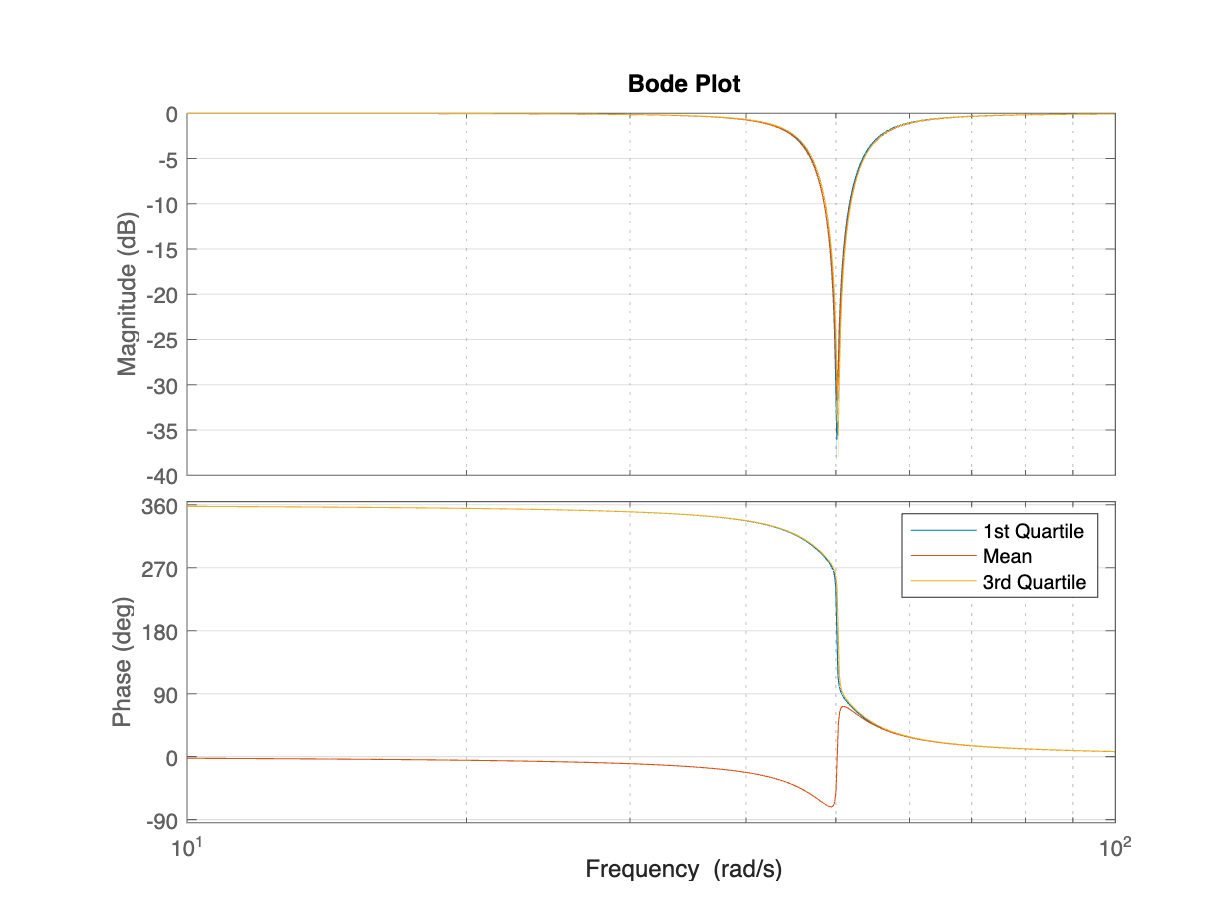

    % Definning Tolerances
    R1_mean = 388e3;                
    R1_tolerance = 0.005;            
    R1_samples =  normrnd(R1_mean, R1_mean * R1_tolerance, number_of_simulations, 1);                    
    R2_mean = 388e3;            
    R2_tolerance = 0.005;            
    R2_samples =  normrnd(R2_mean, R2_mean * R2_tolerance, number_of_simulations, 1);            
    R3_mean = 194e3;            
    R3_tolerance = 0.005;            
    R3_samples =  normrnd(R3_mean, R3_mean * R3_tolerance, number_of_simulations, 1);            
    C1_mean = 8.2e-9;            
    C1_tolerance = 0.005;            
    C1_samples =  normrnd(C1_mean, C1_mean * C1_tolerance, number_of_simulations, 1);         
    C2_mean = 8.2e-9;
    C2_tolerance = 0.005;            
    C2_samples =  normrnd(C2_mean, C2_mean * C2_tolerance, number_of_simulations, 1);            
    C3_mean = 16.4e-9;            
    C3_tolerance = 0.005;        
    C3_samples =  normrnd(C3_mean, C3_mean * C3_tolerance, number_of_simulations, 1);

    R_mean = 388e3;
    C_mean = 8.2e-9;
    frequency = 1 / (2 * pi * R_mean * C_mean);
    w = 2 * pi * frequency;
    s_value = 1i * w;
    gains = zeros(number_of_simulations, 1);
    H_samples = zeros(number_of_simulations, 7); % [[R1,R2,R3,C1,C2,C3,gain], ...]

    % Monte Carlo simulation
    for i = 1:number_of_simulations
        H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_samples(i),R2_samples(i),R3_samples(i),C1_samples(i),C2_samples(i),C3_samples(i),s_value]);
        gains(i) = 20 * log10(abs(double(H)));
        H_samples(i, :) = [R1_samples(i),R2_samples(i),R3_samples(i),C1_samples(i),C2_samples(i),C3_samples(i),gains(i)];
    end

    % Sort results based on gains
    sorted_tfs = sortrows(H_samples, 7);
    
    % Extract first quartile, mean, and third quartile
    q1_index = round(0.25 * number_of_simulations);
    q3_index = round(0.75 * number_of_simulations);
    mean_index = round(0.5 * number_of_simulations);

    % Generate transfer functions for quartiles and mean
    quartiles = [q1_index, mean_index, q3_index];
    tf_list = cell(1, 3);
    f = sym("f");
    for j = 1:3
        R1_val = sorted_tfs(quartiles(j), 1);
        R2_val = sorted_tfs(quartiles(j), 2);
        R3_val = sorted_tfs(quartiles(j), 3);
        C1_val = sorted_tfs(quartiles(j), 4);
        C2_val = sorted_tfs(quartiles(j), 5);
        C3_val = sorted_tfs(quartiles(j), 6);
        Hq = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_val,R2_val,R3_val,C1_val,C2_val,C3_val, 2*pi*f]);
        [num, den] = numden(Hq); % Separate numerator and denominator
        num_coeffs = double(coeffs(num, f, 'All')); % Get numeric coefficients of numerator
        den_coeffs = double(coeffs(den, f, 'All')); % Get numeric coefficients of denominator
        tf_list{j} = tf(num_coeffs, den_coeffs); % Create transfer function
    end

    figure;
    options = bodeoptions;
    options.PhaseVisible = 'off';
    hold on;
    bode(tf_list{1}, {10, 100}, options);
    bode(tf_list{2}, {10, 100}, options);
    bode(tf_list{3}, {10, 100}, options);
    grid on;
    title('Bode Plot');
    legend('1st Quartile', 'Mean', '3rd Quartile');
    hold off;

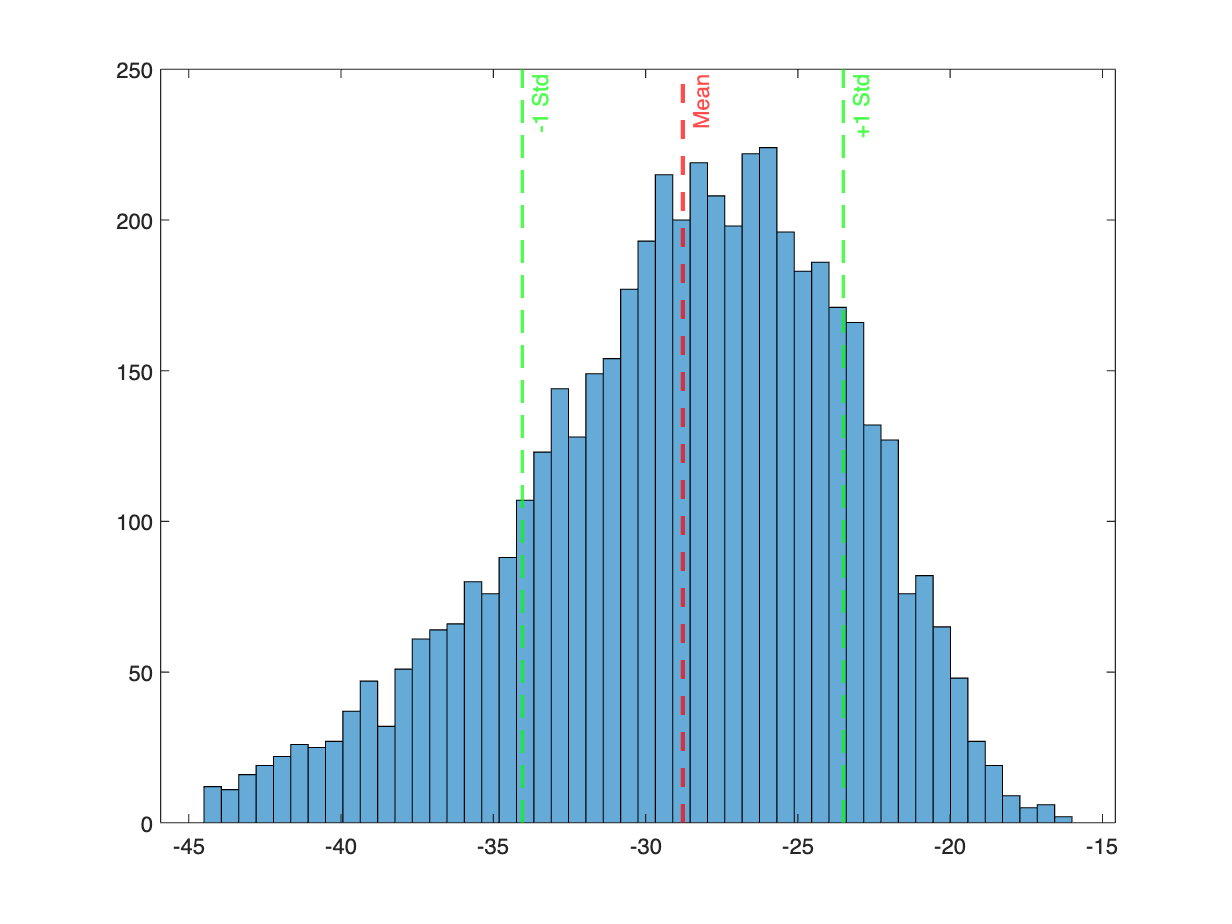


    % Plot Bode diagrams for the quartiles and mean
    figure;
    gains = rmoutliers(gains);
    mean_gain = mean(gains);
    std_gain = std(gains);
    histogram(gains,50);
    xline(mean_gain, '--r', 'LineWidth', 2, 'Label', 'Mean');
    xline(mean_gain + std_gain, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(mean_gain - std_gain, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

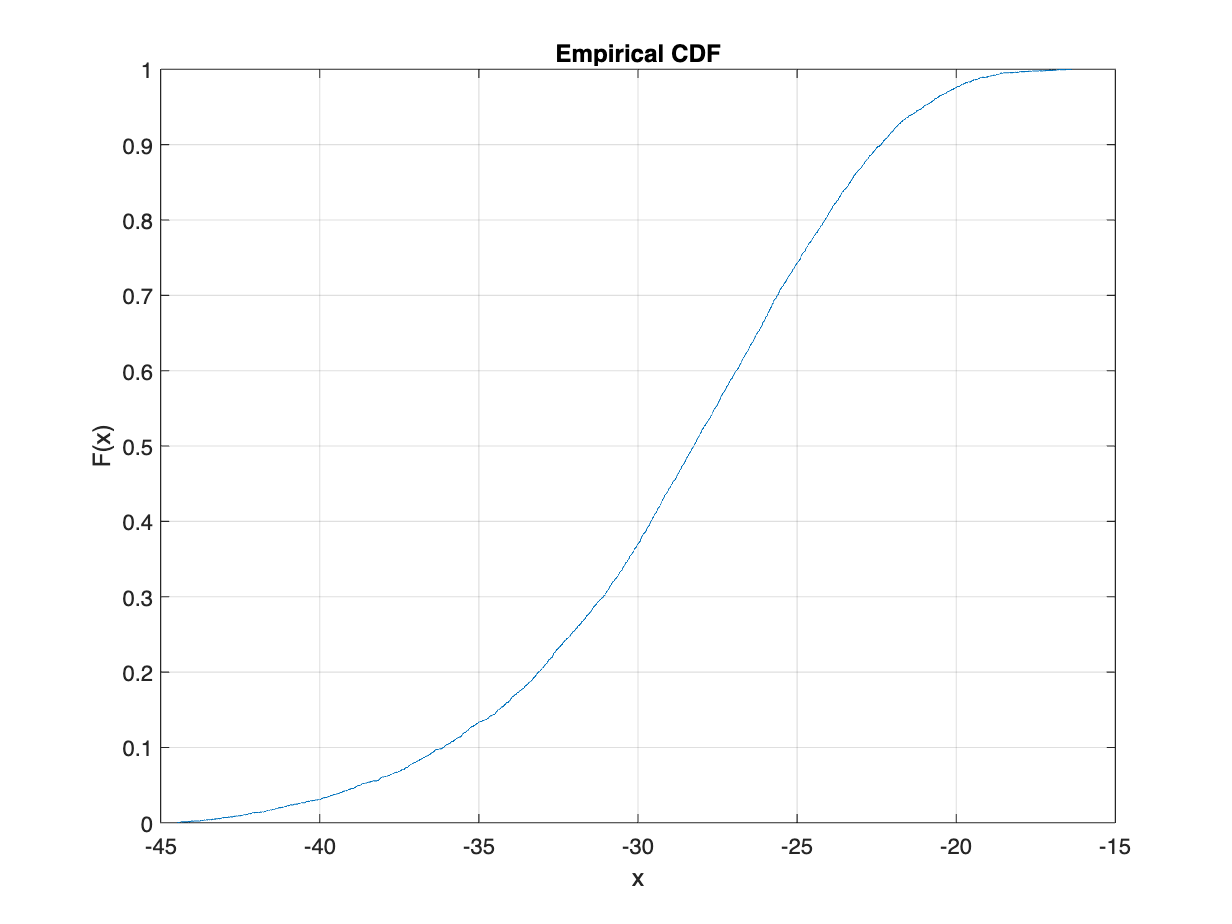

    figure();
    cdfplot(gains);

## 2% Tolerance.

% Monte Carlo Analysis
clc;
clear;

% Number of simulations
number_of_simulations = 1000;

% Defining symbolic transfer function H(s)
syms vo vin v1 v2 v3 C1 C2 C3 R1 R2 R3 s
eq1 = C2*s * (vo - v1) + (vo - v3)/R2 == 0;
eq2 = C1*s * (v1 - vin) + C2*s * (v1 - vo) + (v1 - v2)/R3 == 0;
eq3 = (v2 - v1)/R3 + v2/200 + (v2 - vo)/10 + (v2 - v3) * C3*s == 0;
eq4 = C3*s * (v3 - v2) + (v3 - vin)/R1 + (v3 - vo)/R2 == 0;

solutions = solve([eq1,eq2,eq3,eq4],[v1,v2,v3,vo]);
solVo = simplify(solutions.vo);
H_format = simplify(solVo/vin);
disp(H_format);

    % Definning Tolerances
            R1_mean = 388e3;
            R1_tolerance = 0.2;
            R1_samples =  normrnd(R1_mean, R1_mean * R1_tolerance, number_of_simulations, 1);
            R2_mean = 388e3;
            R2_tolerance = 0.2;
            R2_samples =  normrnd(R2_mean, R2_mean * R2_tolerance, number_of_simulations, 1);
            R3_mean = 194e3;
            R3_tolerance = 0.2;
            R3_samples =  normrnd(R3_mean, R3_mean * R3_tolerance, number_of_simulations, 1);
            C1_mean = 8.2e-9;
            C1_tolerance = 0.2;
            C1_samples =  normrnd(C1_mean, C1_mean * C1_tolerance, number_of_simulations, 1);
            C2_mean = 8.2e-9;
            C2_tolerance = 0.2;
            C2_samples =  normrnd(C2_mean, C2_mean * C2_tolerance, number_of_simulations, 1);
            C3_mean = 16.4e-9;
            C3_tolerance = 0.2;
            C3_samples =  normrnd(C3_mean, C3_mean * C3_tolerance, number_of_simulations, 1);

    R_mean = 388e3;
    C_mean = 8.2e-9;
    frequency = 1 / (2 * pi * R_mean * C_mean);
    w = 2 * pi * frequency;
    s_value = 1i * w;
    gains = zeros(number_of_simulations, 1);
    H_samples = zeros(number_of_simulations, 7); % [[R1,R2,R3,C1,C2,C3,gain], ...]

    % Monte Carlo simulation
    for i = 1:number_of_simulations
        H = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_samples(i),R2_samples(i),R3_samples(i),C1_samples(i),C2_samples(i),C3_samples(i),s_value]);
        gains(i) = 20 * log10(abs(double(H)));
        H_samples(i, :) = [R1_samples(i),R2_samples(i),R3_samples(i),C1_samples(i),C2_samples(i),C3_samples(i),gains(i)];
    end

    % Sort results based on gains
    sorted_tfs = sortrows(H_samples, 7);
    
    % Extract first quartile, mean, and third quartile
    q1_index = round(0.25 * number_of_simulations);
    q3_index = round(0.75 * number_of_simulations);
    mean_index = round(0.5 * number_of_simulations);

    % Generate transfer functions for quartiles and mean
    quartiles = [q1_index, mean_index, q3_index];
    tf_list = cell(1, 3);
    f = sym("f");
    for j = 1:3
        R1_val = sorted_tfs(quartiles(j), 1);
        R2_val = sorted_tfs(quartiles(j), 2);
        R3_val = sorted_tfs(quartiles(j), 3);
        C1_val = sorted_tfs(quartiles(j), 4);
        C2_val = sorted_tfs(quartiles(j), 5);
        C3_val = sorted_tfs(quartiles(j), 6);
        Hq = subs(H_format, [R1,R2,R3,C1,C2,C3,s], [R1_val,R2_val,R3_val,C1_val,C2_val,C3_val, 2*pi*f]);
        [num, den] = numden(Hq); % Separate numerator and denominator
        num_coeffs = double(coeffs(num, f, 'All')); % Get numeric coefficients of numerator
        den_coeffs = double(coeffs(den, f, 'All')); % Get numeric coefficients of denominator
        tf_list{j} = tf(num_coeffs, den_coeffs); % Create transfer function
    end

    % Plot Bode diagrams for the quartiles and mean
    figure;
    options = bodeoptions;
    options.PhaseVisible = 'off';
    hold on;
    bode(tf_list{1}, {10, 100}, options);
    bode(tf_list{2}, {10, 100}, options);
    bode(tf_list{3}, {10, 100}, options);
    grid on;
    title('Bode Plot');
    legend('1st Quartile', 'Mean', '3rd Quartile');
    hold off;

    % Plot Histogram for gain at nothc frequency
    figure;
    gains = rmoutliers(gains);
    mean_gain = mean(gains);
    std_gain = std(gains);
    histogram(gains,50);
    xline(mean_gain, '--r', 'LineWidth', 2, 'Label', 'Mean');
    xline(mean_gain + std_gain, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(mean_gain - std_gain, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');
    figure();
    cdfplot(gains);